# 平滑窗

平滑窗（锐化窗）是一个从中心峰值点向两侧衰落的实函数，在信号处理中用来缓解有限长度信号的**截断影响。**

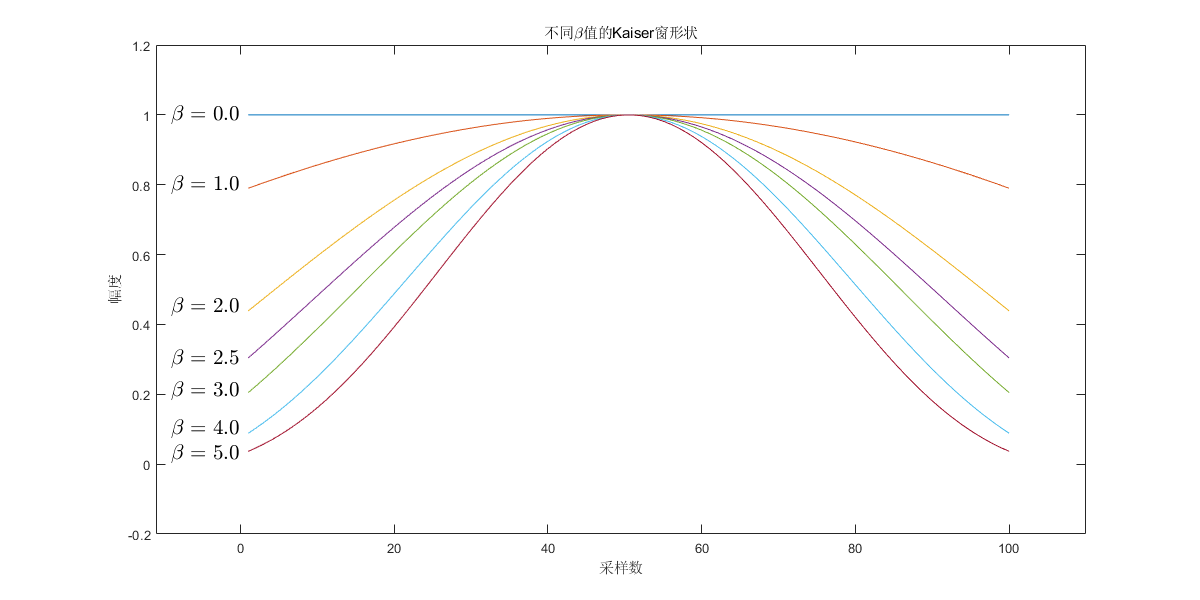

N = 100;
beta = [0,1,2,2.5,3,4,5];

set(figure,'position',[100,100,1200,600]);
for i = 1:1:7
    A = kaiser(N,beta(i));
    
    plot(A),hold on
end

title('不同\beta值的Kaiser窗形状'),xlabel('采样数'),ylabel('幅度')
axis([-11 110,-0.2 1.2])

text('Interpreter','latex','String','$\beta=0.0$','Position',[-9 1.00],'FontSize',16);
text('Interpreter','latex','String','$\beta=1.0$','Position',[-9 0.80],'FontSize',16);
text('Interpreter','latex','String','$\beta=2.0$','Position',[-9 0.45],'FontSize',16);
text('Interpreter','latex','String','$\beta=2.5$','Position',[-9 0.30],'FontSize',16);
text('Interpreter','latex','String','$\beta=3.0$','Position',[-9 0.21],'FontSize',16);
text('Interpreter','latex','String','$\beta=4.0$','Position',[-9 0.10],'FontSize',16);
text('Interpreter','latex','String','$\beta=5.0$','Position',[-9 0.03],'FontSize',16);